# California Case Study for Allocation of Vaccines and Antidotes

*Warning*: This example is intended only to showcase the R0 optimization framework on a simple model of moderate scale. The following results are not recommendations for allocation of resources in response to the COVID-19 pandemic. While R0 optimization could be a valuable tool for planning such real-world allocations, a more carefully-chosen model and cost function would be necessary. 

## Model Construction

Consider a multi-group SEIR model based on the 58 counties in California. For each county i = 1, 2, ..., 58, the epidemic obeys the following dynamics:


$$\dot s_i = \lambda_i -\beta_i \sum_{j=1}^n a_{ij} s_i x_j$$



$$\dot e_i = \beta_i \sum_{j=1}^n a_{ij} s_i x_j - \gamma_i e_i $$



$$\dot x_i = \gamma_i e_i - \delta_i  x_i$$



$$\dot r_i = \delta x_i$$


Here *s* represents the expected number of susceptible individuals, *e* represents exposed individuals who are not yet infectious, *x* represents infectious individuals, and *r* represents "removed" individuals, who can no longer be infected due to immunity or death. The model is parameterized by the following quantities. $\lambda_i$ are the rates at which new individuals are born, $\beta_i$ are the disease transmission rates, $a_{ij}$ are contact rates between pairs of counties, $\gamma_i$ are the rates at which exposed individuals transition into the infectious state, and $\delta_i$ are the rates at which infected individuals are removed. 

% Load empirical parameters
P = load('./data/CA-counties-P.csv');   % Matrix of county visitation probs
s0 = load('./data/CA-counties-s0.csv'); % Vector of county populations
scale = 2.3667e-07;                     % Ensure that R0 = 2.5
A = scale * (P * P');                   % Approx. matrix of inter-county contact rates

% Specify epidemic parameters
beta = 0.1;         % Transmission rate
gamma = 1 / 5;      % 1 / latent infection time
delta = 1 / 10;     % 1 / duration of infectious period

% Create model with uniform epidemic parameters
n = size(A, 1);
beta = beta * ones(n, 1); 
gamma = gamma * ones(n, 1);
delta = delta * ones(n, 1);
model = SEIR(beta, gamma, delta, s0, A); 
disp(['R0 pre-intervention: ' num2str(model.R0())])

R0 pre-intervention: 2.5013



% Seed infection 
i0 = s0 * 0.001;
x0 = [s0; zeros(n, 1); i0; zeros(n, 1)]; 

## Allocation of Pharmaceuticals

Consider two types of pharamceutical interventions: vaccines, which reduce local transmission rates $\beta_i$, and antidotes, which increase local removal rates $\delta_i$. Following [Preciado et. al.](https://ieeexplore.ieee.org/document/6763066), the local vaccination costs are


$$f_i(\beta_i) = \frac{\beta_i^{-1} - \overline{\beta_i}^{-1}}{\underline{\beta_i}^{-1} - \overline{\beta_i}^{-1}}$$


where $\underline{\beta_i}$ and $\overline{\beta_i}$ are lower and upper bounds on $\beta_i$; and local antidote costs are


$$g_i(\delta_i) = \frac{(\tilde \delta_i - \delta_i)^{-1} - (\tilde \delta_i - \underline{\delta_i})^{-1}}{(\tilde \delta_i - \overline{\delta_i})^{-1} - (\tilde \delta_i - \underline{\delta_i})^{-1}} $$


where $\underline \delta_i$ and $\overline \delta_i$ are lower and upper bounds on $\delta_i$, and $\tilde \delta_i > \overline{\delta_i}$ is an additional shape parameter. Thus, the overall cost of the pharmaceutical allocation is


$$c(\beta, \delta) = \sum_{i=1}^{58} f_i(\beta_i) + g_i(\delta_i)$$


We assume unifrom values of these cost parameters across each county.

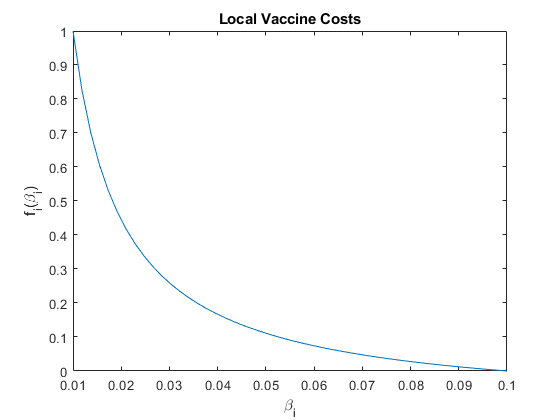

% Create resource allocator
betaRange = [0.1 * beta beta];
deltaRange = [delta 5 * delta]; 
alloc = SEIRAllocator(model, betaRange, deltaRange, 1);

% Plot local vaccine cost curve
figure;
bb = linspace(betaRange(1,1), betaRange(1,2), 50);
ff = (alloc.fSlope(1) ./ bb) - alloc.fOffset(1);
plot(bb, ff);
xlabel('\beta_i');
ylabel('f_i(\beta_i)')
title('Local Vaccine Costs');

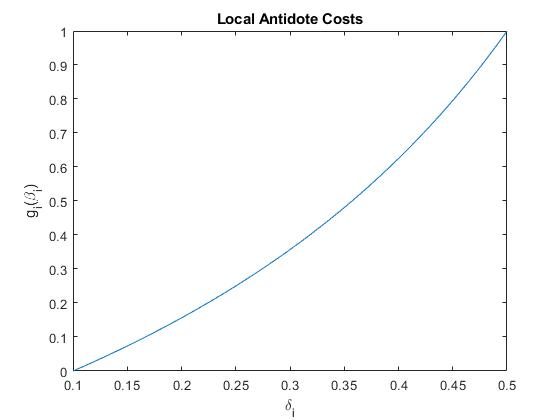


% Plot local antidote cost curve
figure;
dd = linspace(deltaRange(1,1), deltaRange(1,2), 50);
gg = (alloc.gSlope(1) ./ (1 - dd)) - alloc.gOffset(1);
plot(dd, gg);
xlabel('\delta_i');
ylabel('g_i(\beta_i)')
title('Local Antidote Costs');

 Note that local costs all range between 0 and 1, and these bounds are attained at the endpoints of the feasible intervals for $\beta_i$ and $\delta_i$. 

## Solve Allocation Problem

We will now solve the allocation problem for various budgets.

%% WARNING: This block will take several minutes to run. 

% Specify range of budgets
budget = 0 : 0.25 : 10;
nBudget = length(budget);

% Store results for R0 target
R0R0 = zeros(nBudget, 1);
alphaR0 = zeros(nBudget, 1); 
vaxAllocR0 = zeros(nBudget, n);  
antiAllocR0 = zeros(nBudget, n);
totalInfxR0 = zeros(nBudget, n);

% Store results for absc target
alphaAbsc = zeros(nBudget, 1);
R0Absc = zeros(nBudget, 1);
vaxAllocAbsc = zeros(nBudget, n);
antiAllocAbsc = zeros(nBudget, n);
totalInfxAbsc = zeros(nBudget, n); 

for k = 1 : length(budget)
    
    % Perform resource allocation
    [R0R0(k, 1), vaxAllocR0(k, :), antiAllocR0(k, :), modelR0] = ...
        alloc.allocatePharmaR0(budget(k));
    [alphaAbsc(k, 1), vaxAllocAbsc(k, :), antiAllocAbsc(k, :), modelAbsc] = ...
        alloc.allocatePharmaAbscissa(budget(k));
    
    % Compute remaining spectral properties
    alphaR0(k, 1) = modelR0.abscissa();
    R0Absc(k, 1) = modelAbsc.R0();

    % Compute cumulative infections for each post-intervention model
    totalInfxR0(k, :) = modelR0.totalInfections(x0);
    totalInfxAbsc(k, :) = modelAbsc.totalInfections(x0);
      
end

Finally, we plot some interesting properties of the solutions:

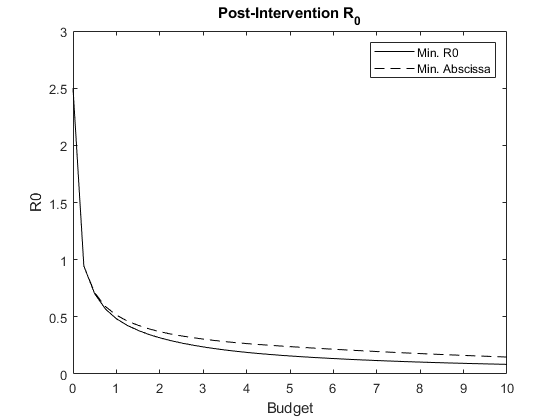

figsize = [3 2.5];

figure;  
set(gcf, 'PaperUnits', 'inches');
set(gcf, 'PaperPosition', [0 0 figsize]);
set(gcf, 'PaperSize', figsize);
plot(budget, R0R0, 'k', budget, R0Absc, 'k--');
xlabel('Budget');
ylabel('R0');
title('Post-Intervention R_0');
legend({'Min. R0', 'Min. Abscissa'}, 'Location', 'northeast');

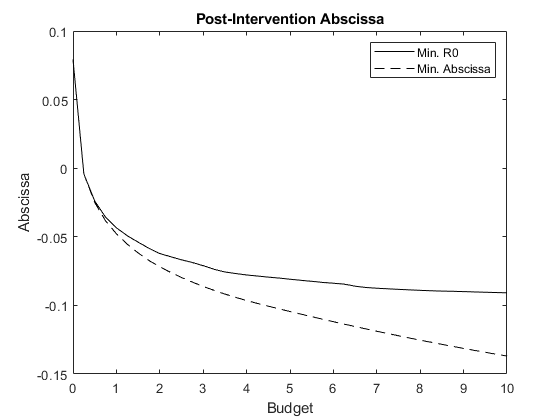


figure; 
set(gcf, 'PaperUnits', 'inches');
set(gcf, 'PaperPosition', [0 0 figsize]);
set(gcf, 'PaperSize', figsize);
plot(budget, alphaR0, 'k', budget, alphaAbsc, 'k--');
xlabel('Budget');
ylabel('Abscissa');
title('Post-Intervention Abscissa');
legend({'Min. R0', 'Min. Abscissa'}, 'Location', 'northeast'); 

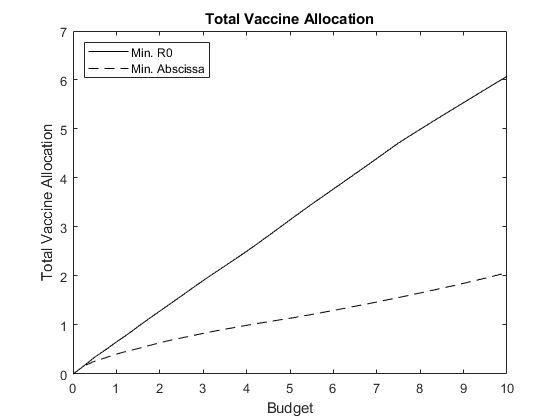


figure; 
set(gcf, 'PaperUnits', 'inches');
set(gcf, 'PaperPosition', [0 0 figsize]);
set(gcf, 'PaperSize', figsize);
plot(budget, sum(vaxAllocR0, 2), 'k', budget, sum(vaxAllocAbsc, 2), 'k--');
xlabel('Budget'); 
ylabel('Total Vaccine Allocation');
title('Total Vaccine Allocation');
legend({'Min. R0', 'Min. Abscissa'}, 'Location', 'northwest'); 

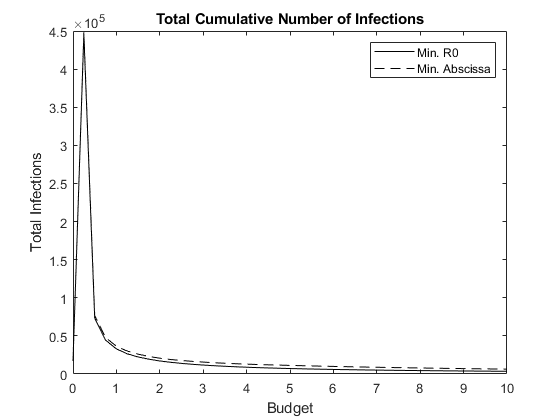


figure; 
set(gcf, 'PaperUnits', 'inches');
set(gcf, 'PaperPosition', [0 0 figsize]);
set(gcf, 'PaperSize', figsize);
plot(budget, sum(totalInfxR0, 2), 'k', budget, sum(totalInfxAbsc, 2), 'k--');
xlabel('Budget');
ylabel('Total Infections');
title('Total Cumulative Number of Infections');
legend({'Min. R0', 'Min. Abscissa'}, 'Location', 'northeast'); 

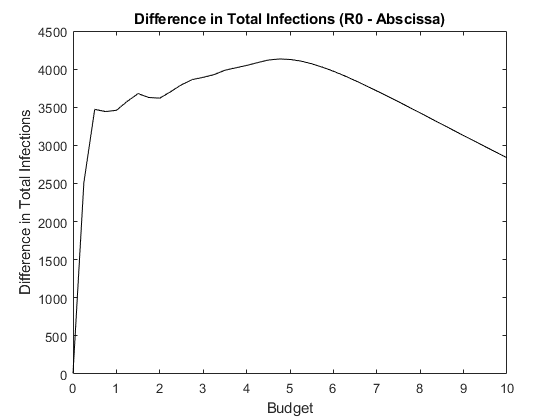


figure;
set(gcf, 'PaperUnits', 'inches');
set(gcf, 'PaperPosition', [0 0 figsize]);
set(gcf, 'PaperSize', figsize);
plot(budget, sum(totalInfxAbsc, 2) - sum(totalInfxR0, 2), 'k');
xlabel('Budget');
ylabel('Difference in Total Infections');
title('Difference in Total Infections (R0 - Abscissa)');